# Lab 4

**Physics 434**

**Francesca Bennett**

Collaborators: Taylor Prewitt, Natalie Shen

## **Problem 1**

### **Part 1				**

*Make a few plots**, generally exploring your data and making sure you understand it. Give a **high level description of the data features** you see. Specifically comment on whether you **see signal contamination** in your data, and how you plan to** build a background pdf()**. *

**Importing the data:**

clear all; close all;

%Four data sets: Time (GPS seconds), Solar phase (deg),
%Earth longitude (deg), and particle counts
labdata = h5read('gammaray_lab4.h5','/data');

h5disp('gammaray_lab4.h5','/data')

HDF5 gammaray_lab4.h5 
Dataset 'data' 
    Size:  25920001x4
    MaxSize:  25920001x4
    Datatype:   H5T_IEEE_F64LE (double)
    ChunkSize:  []
    Filters:  none
    FillValue:  0.000000



%What does this do
labdata(:, :);

**Plots:**

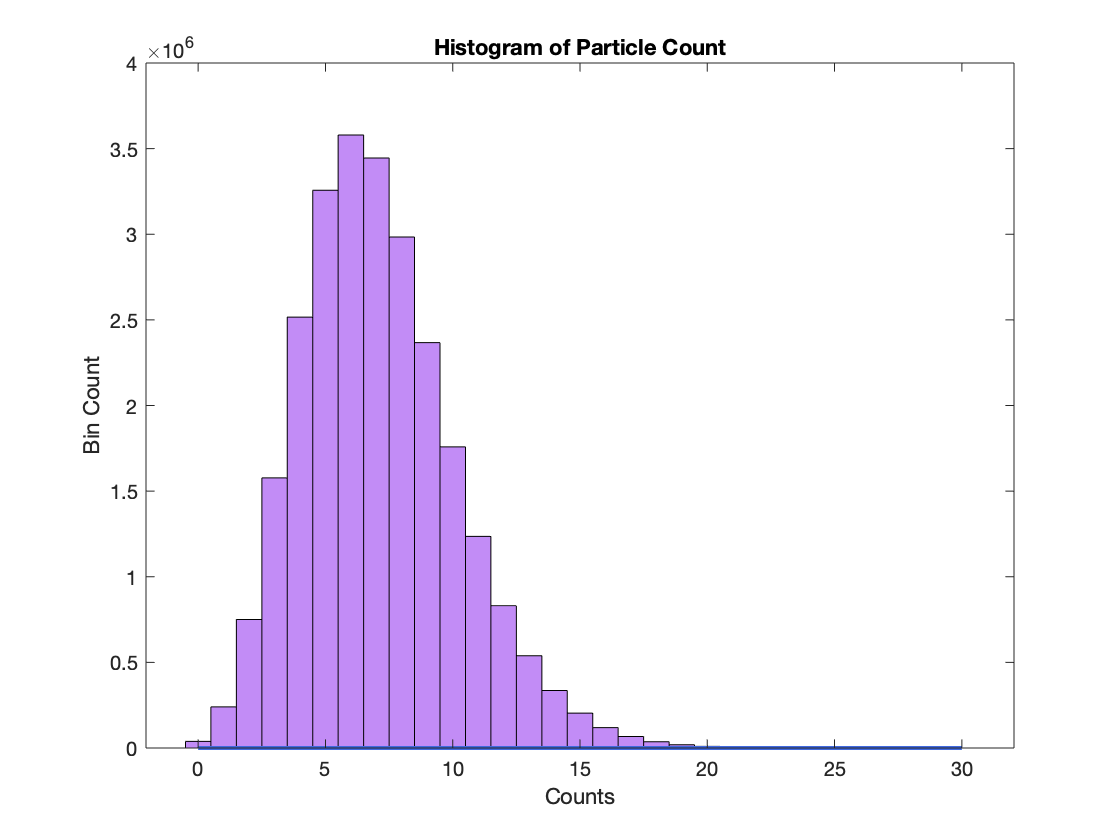

%Particle Count (column 4)
Counts=[labdata(:,4)];

%THIS IS THE BACKGROUND DISTRIBUTION
h4=histogram(Counts,'BinMethod',"auto");
set(h4(1),'FaceColor',"[0.6 0.25 0.94]");
%xlim([11,13]);
title("Histogram of Particle Count"); xlabel("Counts"); 
ylabel("Bin Count");
hold on

%comparing to a poisson
pd = fitdist(Counts,"Poisson");
y = pdf(pd,Counts);
plot(Counts,y,"LineWidth",2,"Color",'[0.25 0.41 0.88]')
hold off


%FIT POISSON NOT WORKINGGGGG (above), the yaxis is too squished 
%ALSO THEORETICAL ARGUMENT ABOUT WHY IT COULD BE EXPECTed TO BE POISSON



The above histogram of the particle counts 

Time versus Other Variables

Time=[labdata(:,1)];

Sun=[labdata(:,2)];

Earth=[labdata(:,3)];

%subplot(2,2,1)
s1=scatter(Earth, Counts);
title("Scatter of Counts vs Earth Longitude"); xlabel("Earth Longitude (degrees)"); 
ylabel("Counts");

%subplot(2,2,2)
s2=scatter(Sun, Counts);
title("Scatter of Counts vs Solar Phase"); xlabel("Solar Phase (degrees)"); 
ylabel("Counts");

%subplot(2,2,3)
s3=scatter(Time, Counts);
title("Scatter of Counts vs Time"); xlabel("Time (GPS seconds)"); 
ylabel("Counts");

%subplot(2,2,4)
%2D Histogram
h = histogram2(Earth,Counts,'DisplayStyle','tile','ShowEmptyBins','off');
title("2D Histogram of Counts vs Earth Longitude"); xlabel("Counts"); 
ylabel("Earth Longitude (degrees)");

In the 2D histogram "2D Histogram of Counts vs Earth Longitude," we see that there is a curve to the density of particles counts; brighter areas on the plot (such as yellow) indicate greater density of particles counted.

### **Part 2**						

*2) The background is ****not ****consistent across the dataset. Find and describe as accurately as you can how the background changes. *

Of our three indepedent variables that counts seen depend on (Solar Phase, Earth longitude, and time), the basic scatter plots of Solar phase vs. counts and GPS time vs. counts are closely similar. The scatter plot of Earth longitude vs. counts, however, shows sigificant variation from these first two scatter plots.

The Earth longitude vs. counts plot shows an ongoing, sloped decay in the number of particles seen, before spiking up and then decaying again.

To isolate this behavior, we can take the average counts over an interval, and plot those on a graph. This will show us how the counts are changing over time, correlated with Earth longitude theta, and allow us to develop a model (Part 3).

%Create a matrix with two columns, 1st column of Earth, 2nd of Counts
E=labdata(:,3);
E(1,:)=[];
E;

C=labdata(:,4);
C(1,:)=[];
C;

%Combine
EandC=[E C];

%The data in column 1 (Earth in degrees) is sorted in ascending value
%Counts are resorted according to their corresponding theta value
S=sortrows(EandC);
S1=S(:,2);

%Use intervals of 1000 data points and average the values for
%(theta, counts) so that we can plot the average lambda values 
%of the scatter plot

S2=reshape(S1,10000,[]);
Y = sum(S2,1)./size(S2,1);
Ave = reshape(repmat(Y, size(S2,1),1),1,[]);

plot(Ave, "Color",'[0.4940 0.1840 0.5560]',"LineWidth",2)
title("Averaged Lambda Plot"); xlabel("Range"); 
ylabel("Counts");

From the Averaged Lambda Plot, we can clearly see the curve that is similar to the top slope of the Earth longitude vs. Counts scatterplot.

The background is not consistent, since the Counts we expect to see are time-dependent. (The degree of Earth longitude is changing with time.) The Counts seen decrease, nearly level out, and then jump back up again and look to start decreasing again. The plot seems to reflect repeating exponential decay.

### **Part 3**

The distribution found in part 2 is a poisson distribution, but the parameter lambda is varrying with time. We know that lambda must varry because the longitude versus counts plot is not consistent.

        $\rightarrow$Find $\lambda (\theta)$, where $\theta $ is the Earth's longitudinal data, in degrees.

For counts c, the Poisson is 


$$P(c)=\frac{\lambda ^ce^{-\lambda }}{c!}$$


Based on the Earth longitude vs. counts plot, 

**GET LAMBDA FROM CURVE FIT**

$ \lambda (\theta )=C_0e^{-k\theta }$ or something

Develop a time dependent model 

$\rightarrow$We need to model repeating exponential decay and match it to the earth plot

In the Earth longitude versus particle count plot, there is exponential decay occuring if the counts decrease at a rate proportional to the current value:


$$\frac{d(\text{Counts})}{d\text{(longitude)}}=-\lambda\times \text{Counts}$$


Which can be solved to become: $\text{Counts}(longitude)=\text{Counts}_0\times e^{(-\lambda \times longtitude)}$

Using $l=\text{Longitude}$ and $C=\text{Counts}$,


$$C(l)=C_0e^{-\lambda l}$$


Therefore, we must find an appropriate value for $\lambda$, the exponential decay constant, and for $C_0$, the initial quantity of C(l). We should consider the initial value of C(l) to be the greatest count in the distribution, so that our exponential model begins at the peak point of the Earth longitude vs particle count plot. We can then choose any data set of longitude and particle count to solve for lamba.

%Max particle count
Max = max(Counts)

Max = 30

Min = min(Counts)

Min = 0

%we find that the max number of counts is 30

c1 = Counts(10)

c1 = 8

l1 = Earth(10)

l1 = 45.0600

RE = range(Earth)

RE = 359.9933

Values for C, l: (countnumber, longitude)


$$C=C_0e^{-\lambda l}$$



$$\ln{\frac {C}{C_0}}=-\lambda l$$



$$\lambda=-\frac1l \ln{\frac{C}{C_0}}$$



$$\lambda=-\frac{1}{45} \ln{\frac{8}{30}}=0.02937$$


Now, we have our value for the exponential decay constant. Our model is:

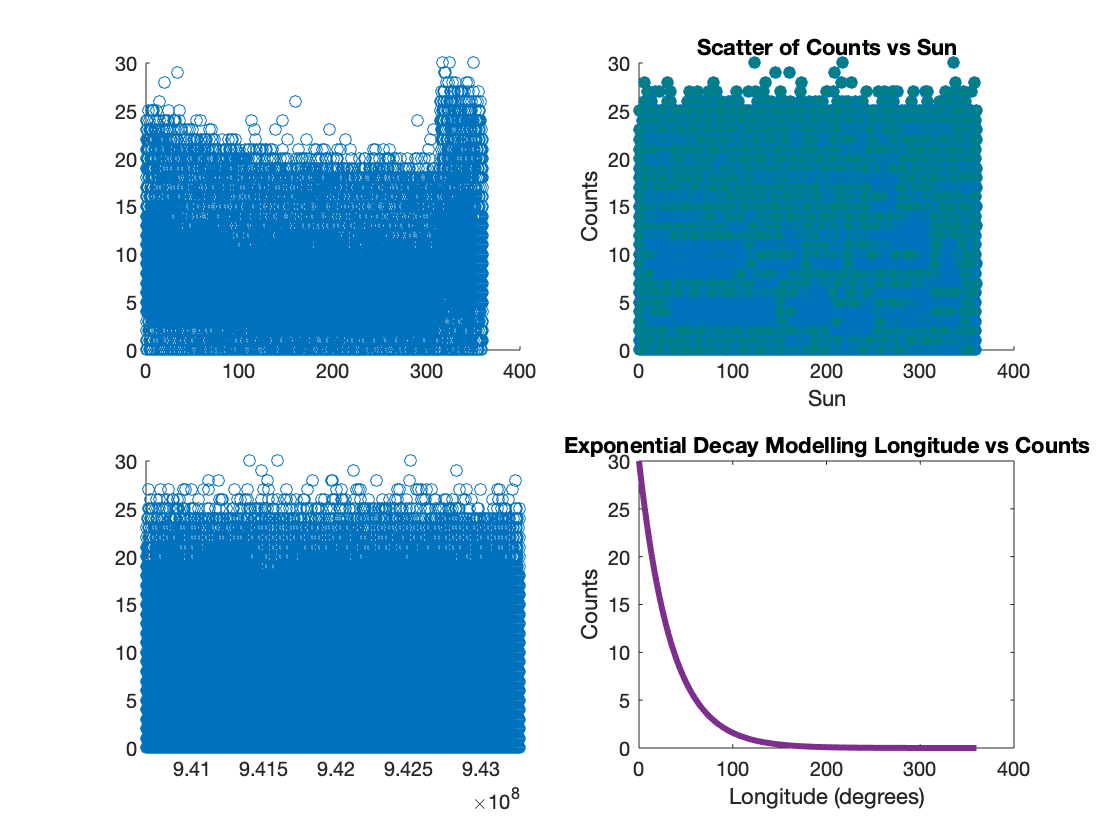

%Plot of model and earth decay on same grid
%NO LONGER CORRECT/WHAT TO USE

t = Time;
l = [0:.5:360];
X = 0.02937*l;
C = 30*exp(-X);
plot(l,C,'LineWidth',3,"Color", [0.4940 0.1840 0.5560])
title("Exponential Decay Modelling Longitude vs Counts")
xlabel("Longitude (degrees)");ylabel("Counts")

What about C(t)?

t1 = Time(10)

t1 = 9.4068e+08


$$C(t)=C_0e^{-\lambda t}$$



$$C_1=C_0e^{-\lambda t_1}$$



$$\ln{\frac {C_1}{C_0}}=-\lambda t_1$$



$$\lambda=-\frac1t_1 \ln{\frac{C_1}{C_0}}$$



$$\lambda=-\frac{1}{t} \ln{\frac{C_1}{C_0}}$$


**Part 4**					

4) Because the background varies, your discovery sensitivity threshold (how many particles you would need to see) also varies. What is the '5-sigma' threshold for a 100 millisecond GRB at different times? 

Each 100 milliseconds GRB timeframe is a trial, and we have a 90 minute orbit. In 90 minutes, there are $3.6\times 10^{-6}$ milliseconds. If our trials are 100 milliseconds long, we have 36,000 trials of 100 millisecond trials. 

We need to find the 5-sigma threshold for each of these trials.

%One trial
%need first interval of Time that is 100ms=0.1 s long
%if I have a matrix [1 2 3 4 5] how do I take up to the sum that 
%equals 6?
%OR
%each 100 entries in Time is 

%maybe can use: n= number of trials, 8n-4n=ahhhg
%t_trial = Time(n*(4 entries)

**!!! USE PART 3 TRIAL model FOR THIS**

Over 1 100 ms sample of our MODEL, what probability is it that we see XX occurring?

Background varries  $\rightarrow$ "discovery sensitivity threshold": 

Optional: Identify cause of the variable background and propose a physical model.

Strontium particles emit RGB radiation, and are blocked by the Earth from the satellite's view for most of the range of the longitudinal data. When the satellite reaches a point where the Earth is not longer blocking strontium particles, we see the expected particle count maximum occur. Then, the satellite sees the decaying effect of the strontium particles. 

## Problem 2				

**Part 1**

1) Dowload the data from `images.h5 `. This is a stack of 10 square images, each 200 pixels on a side. 

%Import images
% h5disp("images.h5");
% image1=h5read("images.h5","/image1");
% image=h5read("images.h5","/imagestack");





**Part 2	**					

2) Explore the data. Is there signal contamination? Is the background time dependent? Is it consistent spatially? Develop a plan to calculate your background pdf(). 

Consistent (i.e. non transient) stars should be in all 10 images

$\rightarrow$find a way to check for large variation between the images

$\rightarrow$look at data, find areas that are inconsistent

Part 4

4) You and your lab partner had different pdf(), but were using the *same *data. Explore why this is. 

We are looking for different phenomena in the data. One goal is to find 